clear all
clc
addpath('H:\GIT project\Instrumentation\HW2\')

Studen_Num=810199492

Studen_Num = 810199492

Y = HW2_sig(810199492)

Y =     0.3024    1.1417   -1.0494    0.8160    0.6204   -0.1845    0.4164    0.9619    2.8899    2.5428    0.3335    2.9057    1.7127    1.3741    1.9153    1.5010    1.6482    2.6564    2.7105    2.8133    2.4908    1.5296    2.7060    3.3119    2.7611    3.1573    3.0719    2.5784    2.9984    2.4727    3.4954    2.4293    2.5497    2.7701    1.6420    4.1768    3.6190    3.0776    4.3364    2.6649    3.6291    3.6077    3.9776    4.0262    3.4137    3.9306    3.8997    4.3880    4.6898    4.7364


t =linspace(0,10,numel(Y))

t =          0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


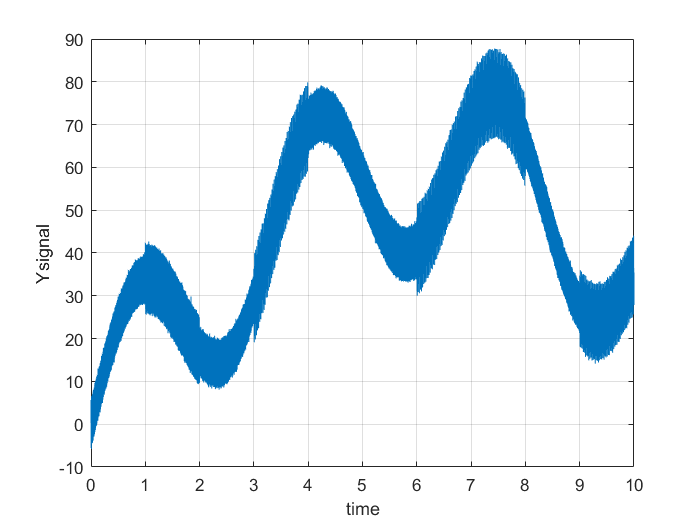

plot(t,Y)
grid on
xlabel('time')
ylabel('Ysignal')

s = tf('s');
f=20

f = 20

RC=1/(2*pi*f)

RC = 0.0080

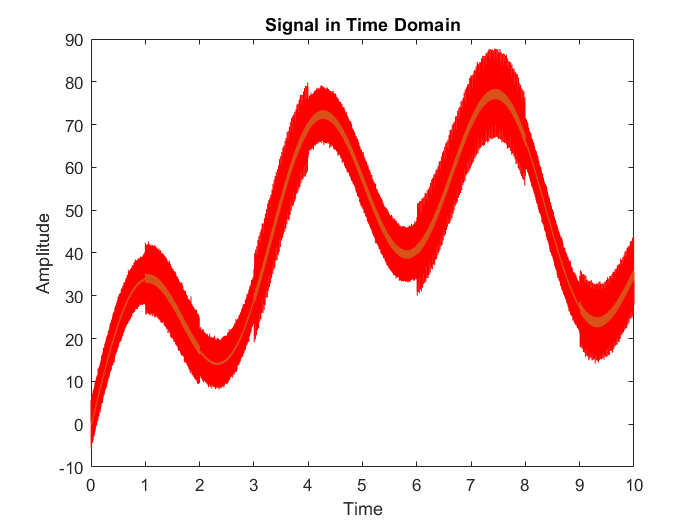


H = (1) / (RC*s+1);

Y_laplace = lsim(H, Y, t);
plot(t, Y,'r'); 
hold On
plot(t, Y_laplace); 

xlabel('Time');
ylabel('Amplitude');
title('Signal in Time Domain');

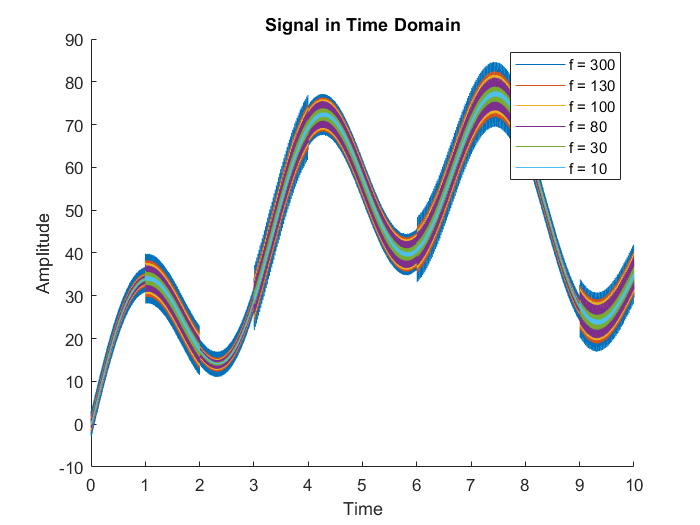

s = tf('s');
f = [10, 30, 80, 100, 130, 300];
f_reversed = flip(f);
RC = 1./(2*pi*f_reversed);

figure;
hold on; 

for i = 1:length(f_reversed)
    H = 1 / (RC(i)*s + 1);
    Y_laplace = lsim(H, Y, t);
    plot(t, Y_laplace);
end
hold off; 

xlabel('Time');
ylabel('Amplitude');
title('Signal in Time Domain');
legend('f = 300',  'f = 130', 'f = 100', 'f = 80' ,'f = 30', 'f = 10');

s = tf('s');
f1 = 90;
f2 = 110;
RC1 = 1/(2*pi*f1);
display(RC1)

RC1 = 0.0018

RC2 = 1/(2*pi*f2);
display(RC2)

RC2 = 0.0014

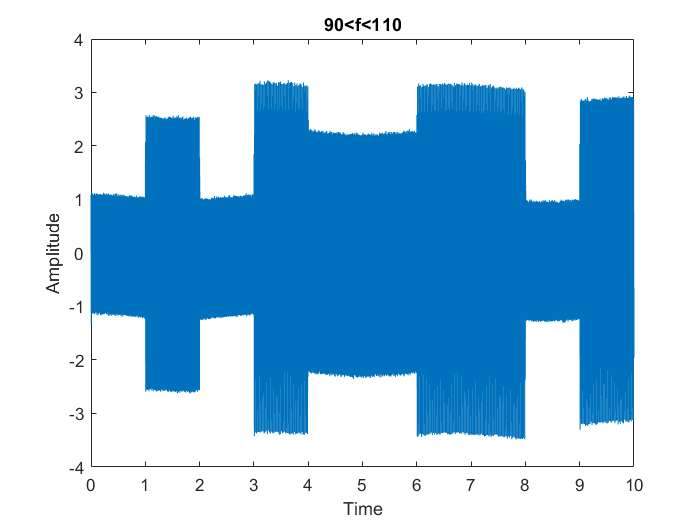

figure;
H = (RC2*s) / ((RC1*s + 1) * (RC2*s + 1));

Y_Q4 = lsim(H, Y, t);

plot(t, Y_Q4); 
xlabel('Time');
ylabel('Amplitude');
title('90<f<110');

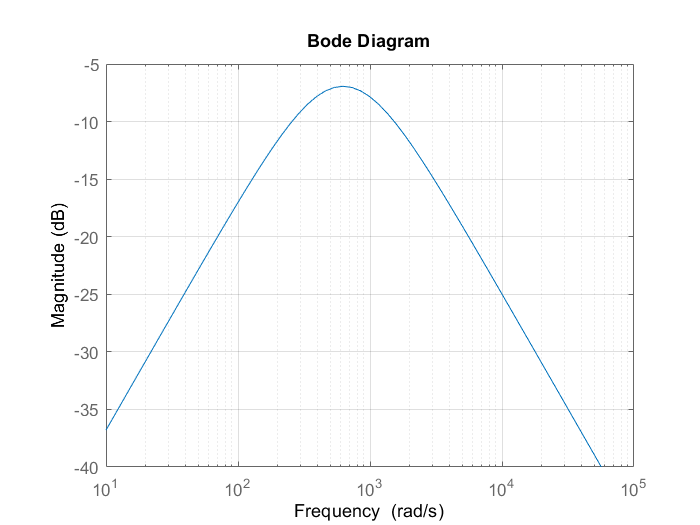

figure
bodemag(H)
grid on


figure
s = tf('s');
f1 = 90;
f2 = 110;
RC1 = 1/(2*pi*f1);
display(RC1)

RC1 = 0.0018

RC2 = 1/(2*pi*f2);
display(RC2)

RC2 = 0.0014

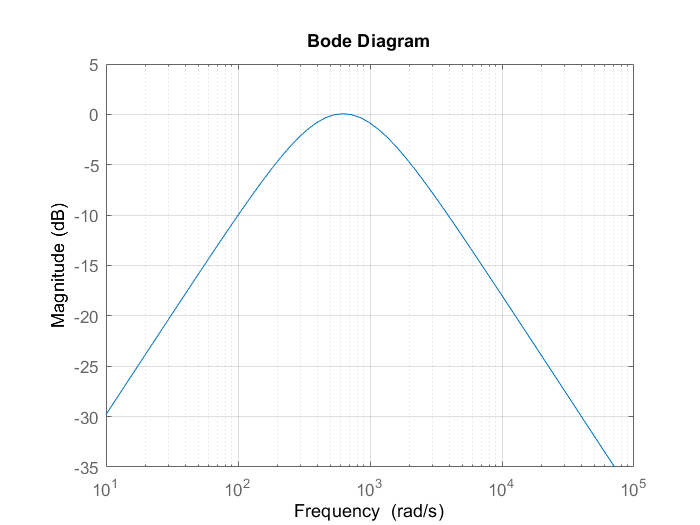

figure;
H = (2.239*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)));
figure
bodemag(H)
grid on

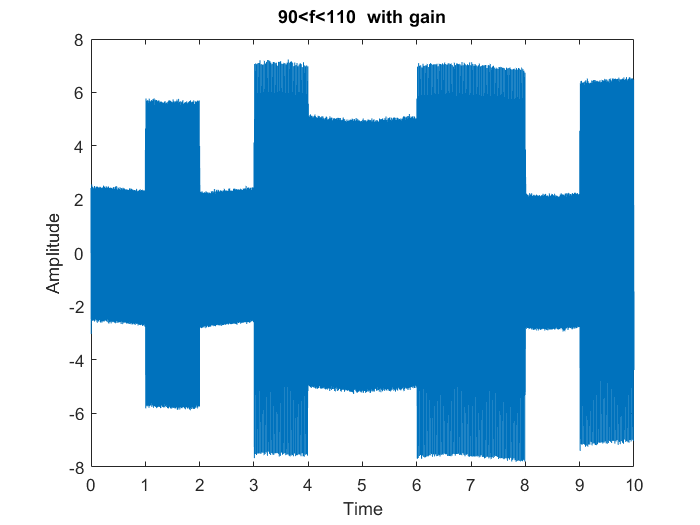

Y_Q4 = lsim(H, Y, t);

plot(t, Y_Q4); 
xlabel('Time');
ylabel('Amplitude');
title('90<f<110 _ with gain');

Q6

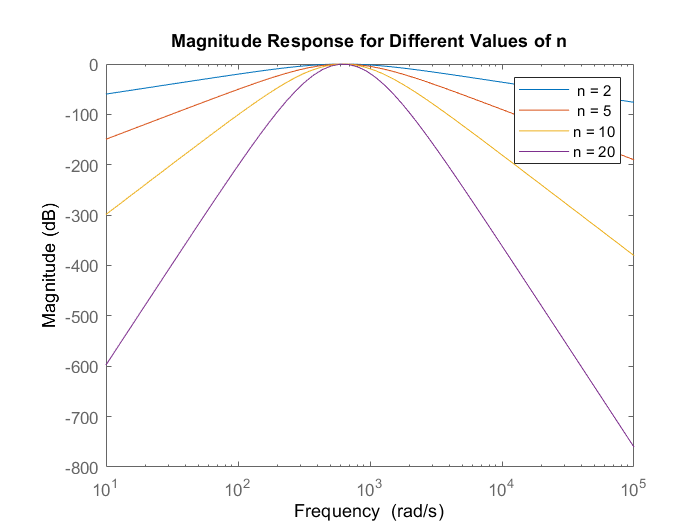

n = [2 ,5, 10, 20];
figure
s = tf('s');
f1 = 90;
f2 = 110;
RC1 = 1/(2*pi*f1);
RC2 = 1/(2*pi*f2);

hold on;
H1 = (2.22*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^2;
bodemag(H1);
H2 = (2.22*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^5;
bodemag(H2);
hold on;
H3 = (2.22*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^10;
bodemag(H3);
hold on;
H4 = (2.22*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^20;
bodemag(H4);


hold off;

legendCell = cellstr(num2str(n', 'n = %d'));
legend(legendCell);
title('Magnitude Response for Different Values of n');

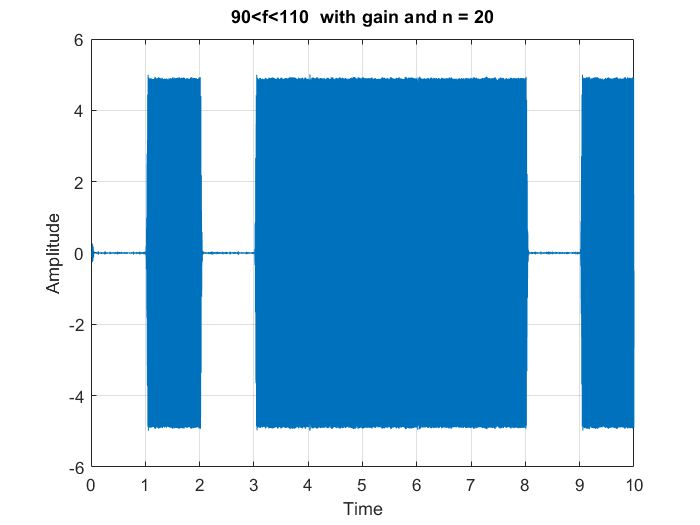


H4 = (2.22*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^20;
figure
Y_Q6 = lsim(H4, Y, t);

plot(t, Y_Q6); 
grid on;
xlabel('Time');
ylabel('Amplitude');
title('90<f<110 _ with gain and n = 20');

Q7-250Hz

s = tf('s');
f1 = 230;
f2 = 270;
RC1 = 1/(2*pi*f1);
display(RC1)

RC1 = 6.9198e-04

RC2 = 1/(2*pi*f2);
display(RC2)

RC2 = 5.8946e-04

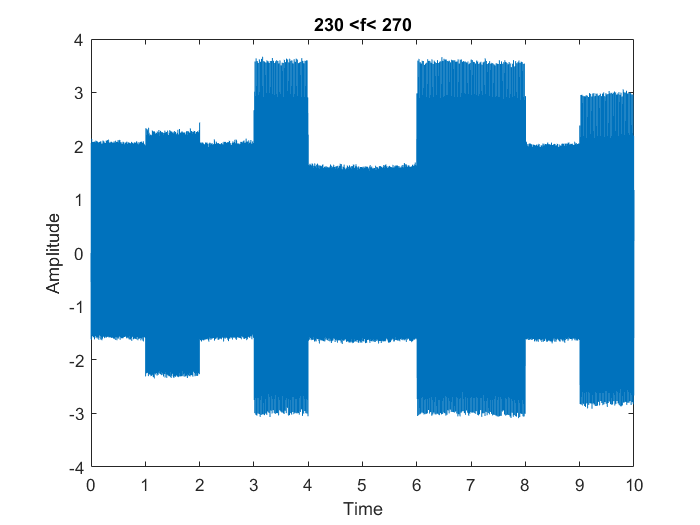

figure;
H = (RC2*s) / ((RC1*s + 1) * (RC2*s + 1));

Y_250 = lsim(H, Y, t);

plot(t, Y_250); 
xlabel('Time');
ylabel('Amplitude');
title('230 <f< 270');

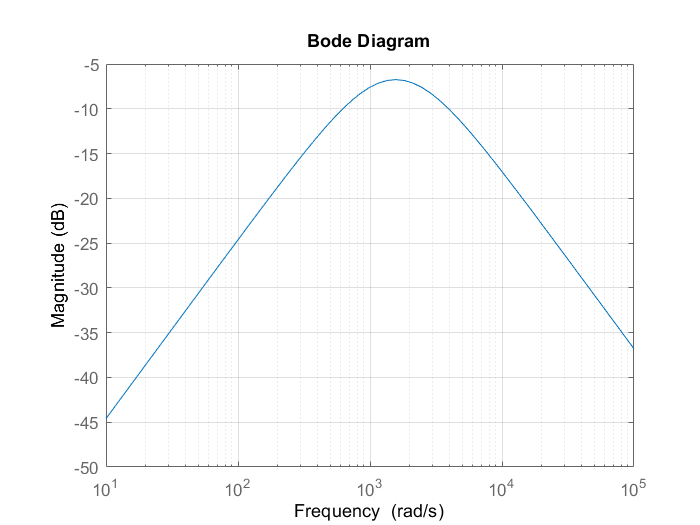

figure
bodemag(H)
grid on


figure
s = tf('s');
f1 = 230;
f2 = 270;
RC1 = 1/(2*pi*f1);
display(RC1)

RC1 = 6.9198e-04

RC2 = 1/(2*pi*f2);
display(RC2)

RC2 = 5.8946e-04

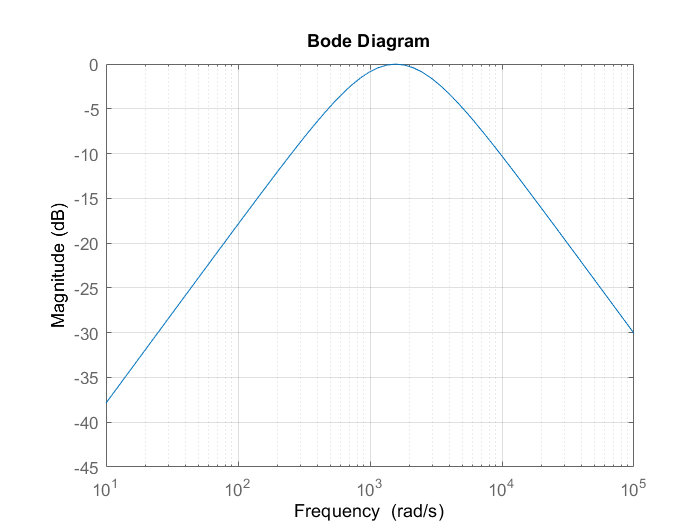

figure;
H = (2.17*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)));
figure
bodemag(H)
grid on

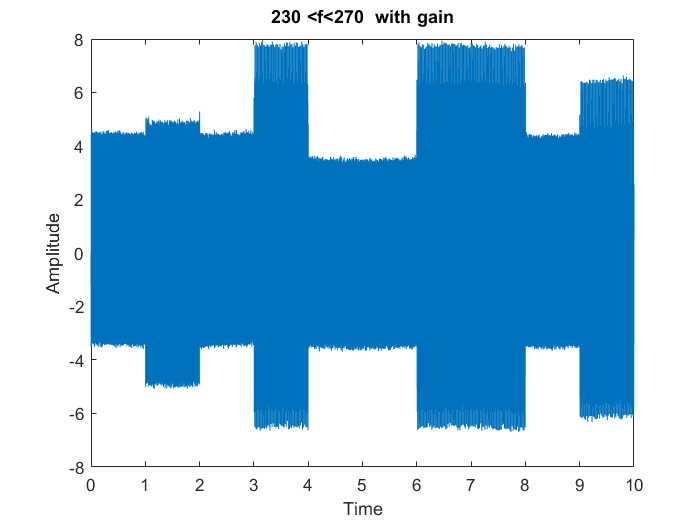

Y_250  = lsim(H, Y, t);

plot(t, Y_250); 
xlabel('Time');
ylabel('Amplitude');
title('230 <f<270 _ with gain');

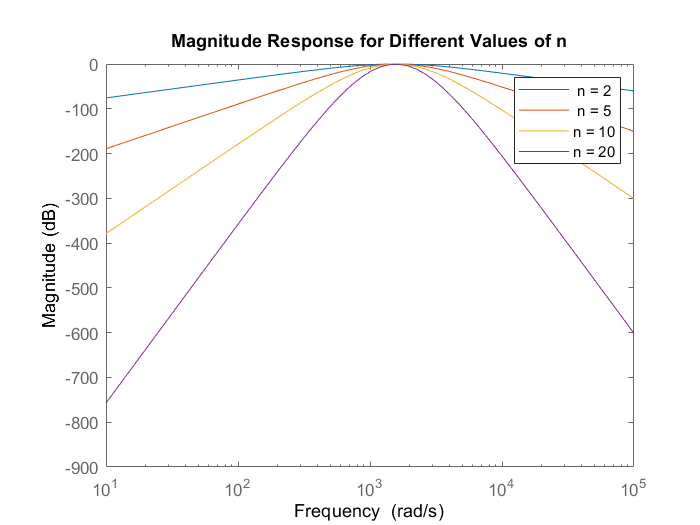

n = [2 ,5, 10, 20];
figure
s = tf('s');
f1 = 230;
f2 = 270;
RC1 = 1/(2*pi*f1);
RC2 = 1/(2*pi*f2);

hold on;
H1 = (2.17*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^2;
bodemag(H1);
H2 = (2.17*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^5;
bodemag(H2);
hold on;
H3 = (2.17*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^10;
bodemag(H3);
hold on;
H4 = (2.17*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^20;
bodemag(H4);


hold off;

legendCell = cellstr(num2str(n', 'n = %d'));
legend(legendCell);
title('Magnitude Response for Different Values of n');

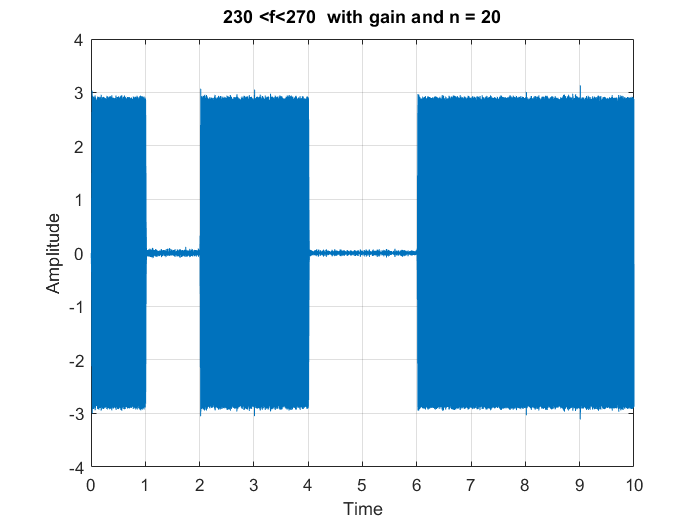


H4 = (2.17*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^20;
figure
Y_250 = lsim(H4, Y, t);

plot(t, Y_250); 
grid on;
xlabel('Time');
ylabel('Amplitude');
title('230 <f<270 _ with gain and n = 20');

Q7-500Hz

s = tf('s');
f1 = 480;
f2 = 520;
RC1 = 1/(2*pi*f1);
display(RC1)

RC1 = 3.3157e-04

RC2 = 1/(2*pi*f2);
display(RC2)

RC2 = 3.0607e-04

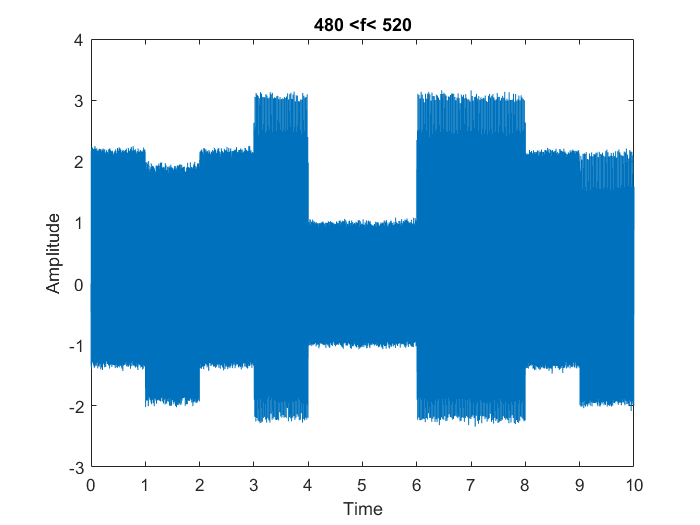

figure;
H = (RC2*s) / ((RC1*s + 1) * (RC2*s + 1));

Y_500 = lsim(H, Y, t);

plot(t, Y_500); 
xlabel('Time');
ylabel('Amplitude');
title('480 <f< 520');

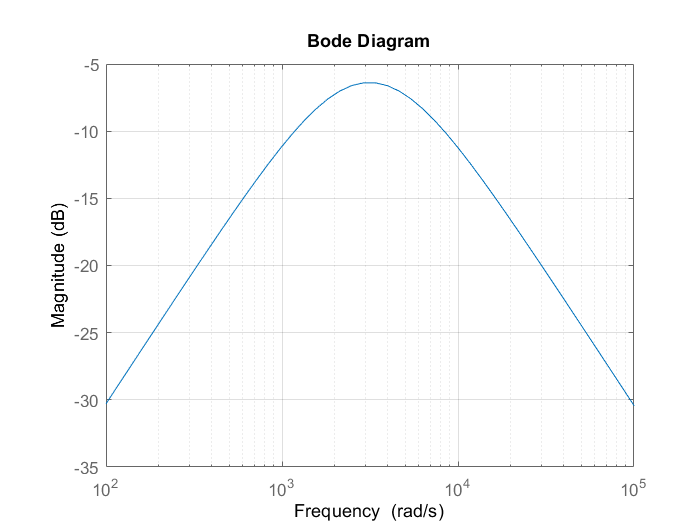

figure
bodemag(H)
grid on


figure
s = tf('s');
f1 = 480;
f2 = 520;
RC1 = 1/(2*pi*f1);
display(RC1)

RC1 = 3.3157e-04

RC2 = 1/(2*pi*f2);
display(RC2)

RC2 = 3.0607e-04

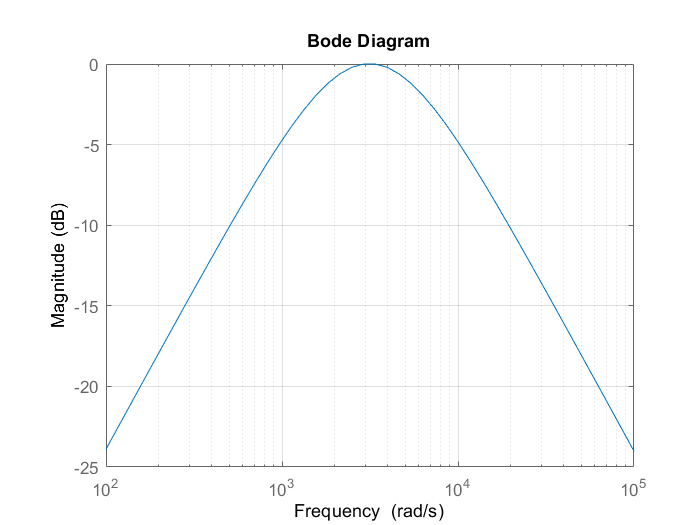

figure;
H = (2.089*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)));
figure
bodemag(H)
grid on

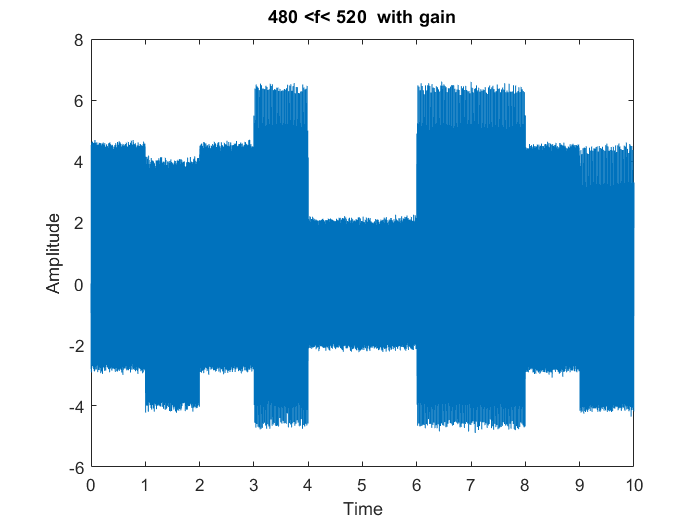

Y_500  = lsim(H, Y, t);

plot(t, Y_500); 
xlabel('Time');
ylabel('Amplitude');
title('480 <f< 520 _ with gain');

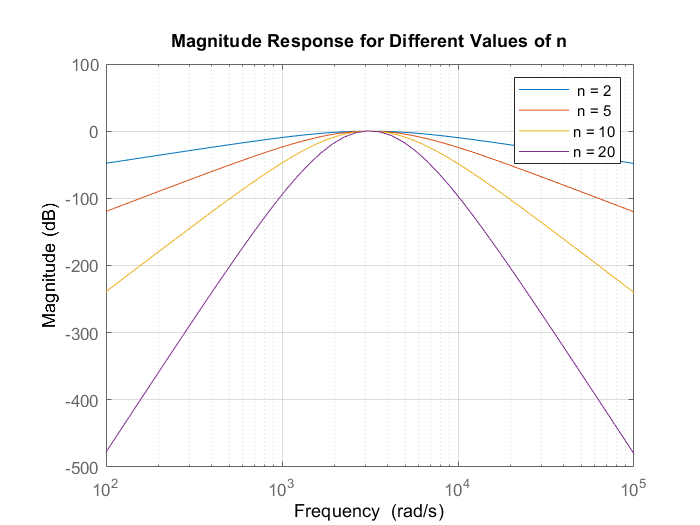

n = [2 ,5, 10, 20];
figure
s = tf('s');
f1 = 480;
f2 = 520;
RC1 = 1/(2*pi*f1);
RC2 = 1/(2*pi*f2);

hold on;
H1 = (2.089*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^2;
bodemag(H1);
H2 = (2.089*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^5;
bodemag(H2);
hold on;
H3 = (2.089*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^10;
bodemag(H3);
hold on;
H4 = (2.089*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^20;
bodemag(H4);
grid on;

hold off;

legendCell = cellstr(num2str(n', 'n = %d'));
legend(legendCell);
title('Magnitude Response for Different Values of n');

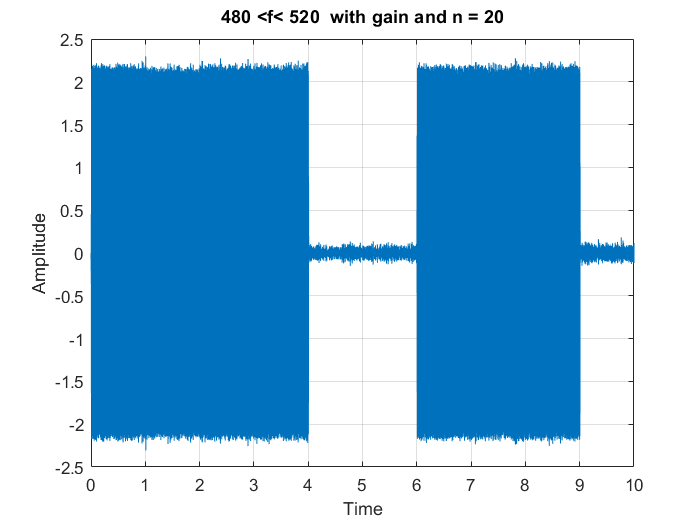


H4 = (2.089*(RC2*s) / ((RC1*s + 1) * (RC2*s + 1)))^20;
figure
Y_500 = lsim(H4, Y, t);

plot(t, Y_500); 
grid on;
xlabel('Time');
ylabel('Amplitude');
title('480 <f< 520 _ with gain and n = 20');

Q9

f=10000

f = 10000

RC=1/(2*pi*f)

RC = 1.5915e-05

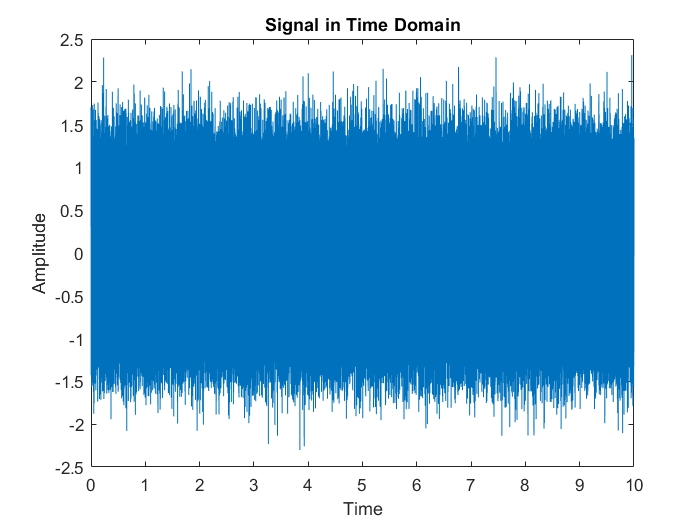

figure;
H = (RC*s) / (RC*s+1);

Y_laplace = lsim(H, Y, t);

plot(t, Y_laplace); 

xlabel('Time');
ylabel('Amplitude');
title('Signal in Time Domain');

Q10


figure;
H2 = (s^2+9869604.4010894) / (s^2+4443.5539654735*s+9869604.4010894);

Y_laplace1 = lsim(H2, Y, t);
Y_wow = Y_laplace1- Y.'

Y_wow =          0
   -0.1520
   -0.1369
   -0.0985
   -0.2333
   -0.2449
   -0.2360
   -0.3462
   -0.7015
   -1.1686


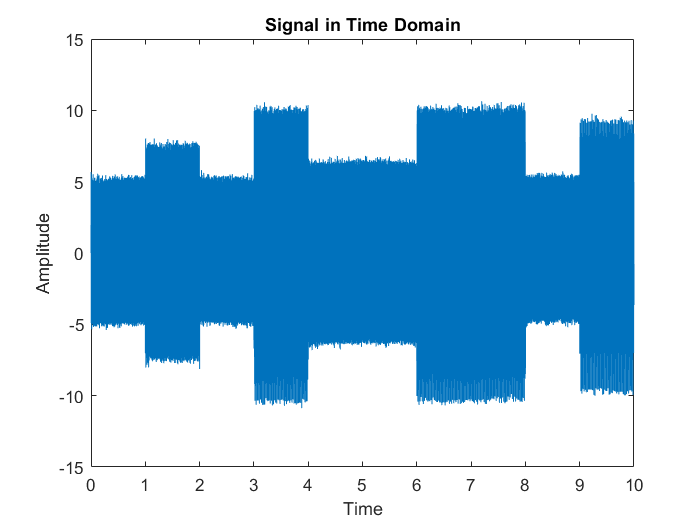

plot(t, Y_wow); 

xlabel('Time');
ylabel('Amplitude');
title('Signal in Time Domain');